Initialise Dataset

close all;
clear all;
inputTable = readtable("../data/Concrete_Data.csv");


% Extract predictors and response
% This code processes the data into the right shape for training the
% model.
predictorNames = inputTable.Properties.VariableNames(1,1:8);
predictors = inputTable(:, predictorNames);
response = inputTable.Concrete_Compressive_Strength_Mpa;

%Print out head of table
display(inputTable(1:10,:))

ans = 10×9 table
    Cement_kgm_3    BlastFurnaceSlag_kgm_3    FlyAshkgm_3    Water_kgm_3    Superplasticizer_kgm_3    CoarseAggregate_kgm_3    FineAggregate_kgm_3    Age_days    Concrete_Compressive_Strength_Mpa
    ____________    ______________________    ___________    ___________    ______________________    _____________________    ___________________    ________    _________________________________

         540                    0                  0             162                 2.5                       1040                     676              28                    79.986              
         540                    0                  0             162                 2.5

Apply T-SNE to allow us to visualise the dataset

%Apply Stochastic Neighbour Embedding for Dimentionality Reduction
Y = tsne(table2array(predictors),'Distance', "cosine",'Standardize',true,"Perplexity",50);
bins = 20;
max(response)

ans = 82.5992

min(response)

ans = 2.3318

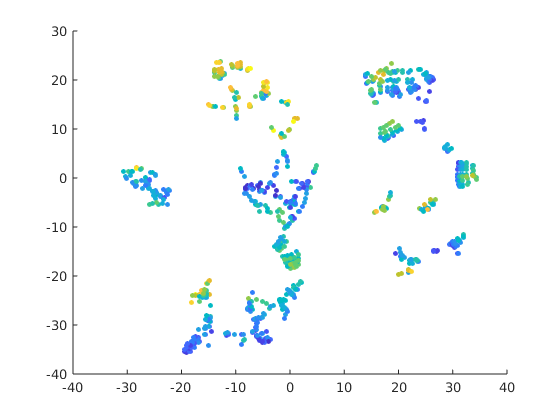

scatter(Y(:,1),Y(:,2),15,discretize(response,bins),"filled");

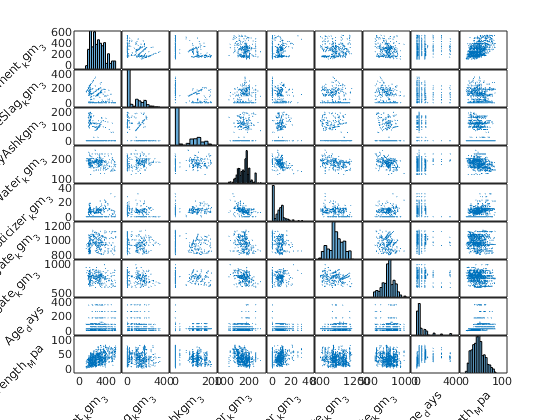

%Create a pairplot to look at cross-correlation

[~,ax] = plotmatrix(table2array(inputTable));
plotSize =width(inputTable);
for k=1:plotSize
ax(k,1).YLabel.String = inputTable.Properties.VariableNames{1,k}; 
ax(k,1).YLabel.Rotation = 45;
ax(k,1).YLabel.HorizontalAlignment = 'right';
ax(plotSize,k).XLabel.String = inputTable.Properties.VariableNames{1,k};
ax(plotSize,k).XLabel.Rotation = 45;
ax(plotSize,k).XLabel.HorizontalAlignment = 'right';

end


%we can also compute the correlation between all features including the response variable 
correlationMatrix = corr(table2array(inputTable));

correlationMatrix =     1.0000   -0.2752   -0.3975   -0.0815    0.0928   -0.1094   -0.2227    0.0819    0.4978
   -0.2752    1.0000   -0.3236    0.1073    0.0434   -0.2840   -0.2816   -0.0442    0.1348
   -0.3975   -0.3236    1.0000   -0.2570    0.3773   -0.0100    0.0791   -0.1544   -0.1058
   -0.0815    0.1073   -0.2570    1.0000   -0.6575   -0.1823   -0.4506    0.2776   -0.2896
    0.0928    0.0434    0.3773   -0.6575    1.0000   -0.2663    0.2225   -0.1927    0.3661
   -0.1094   -0.2840   -0.0100   -0.1823   -0.2663    1.0000   -0.1785   -0.0030   -0.1649
   -0.2227   -0.2816    0.0791   -0.4506    0.2225   -0.1785    1.0000   -0.1561   -0.1672
    0.0819   -0.0442   -0.1544    0.2776   -0.1927   -0.0030   -0.1561    1.0000    0.3289
    0.4978    0.1348   -0.1058   -0.2896    0.3661   -0.1649   -0.1672    0.3289    1.0000


display(correlationMatrix)

Configure limits for Bayesian Hyperparameter Optimization

%Use params = hypermparameters() to set limits for hyperparameter Optimization


Train RandomForest Model and perform Model Selection

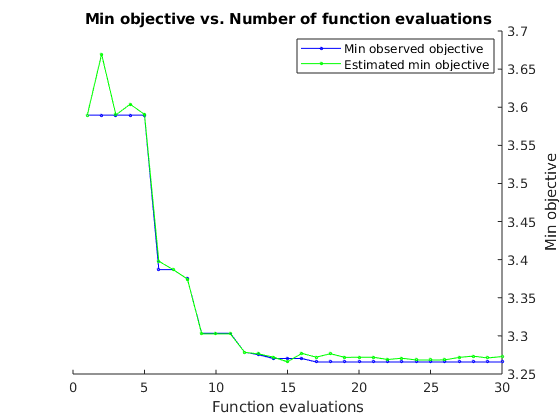

|=================================================================================================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |       Method | NumLearningC-|    LearnRate |  MinLeafSize | MaxNumSplits | NumVariables-|
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              | ycles        |              |              |              | ToSample     |
|=================================================================================================================================================================|
|    1 | Best   |      3.5897 |      6.7476 |      3.5897 |      3.5897 |          Bag |          143 |            - |            2 |           51 |            8 |
|    2 | Accept |      5.1978 |      2.0599 |      3.5897 |      3.6695 |          Bag |           73 |            - |          131 |          816 |            1 |
|    3 | Accept 

%Optimize Model Hyperparameters using bayesian inference (bayesopt)
%EnsembleTree
template = templateTree('Reproducible', true,'Surrogate','on');
regressionEnsemble = fitrensemble(predictors, response, ...
    'Learners', template, ...
    'OptimizeHyperparameters', 'all', ...
    'HyperparameterOptimizationOptions', struct('Optimizer', 'bayesopt', 'AcquisitionFunctionName','expected-improvement-plus', 'Kfold', 5));

Train Gaussian Processes Model and perform Model Selection

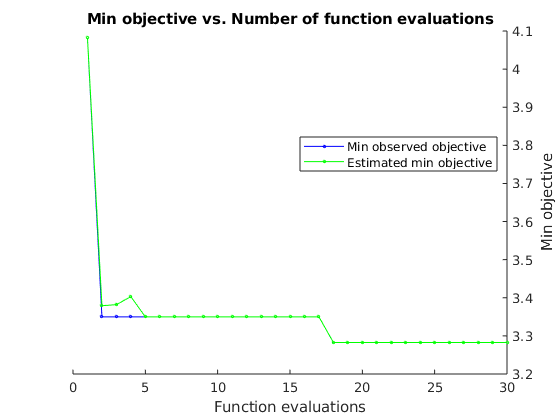

|==================================================================================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |        Sigma | BasisFunction| KernelFuncti-|  KernelScale |  Standardize |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |              | on           |              |              |
|==================================================================================================================================================|
|    1 | Best   |      4.0822 |      9.6592 |      4.0822 |      4.0822 |   0.00012922 |     constant | rationalquad |       1.0034 |        false |
|    2 | Best   |        3.35 |      45.806 |        3.35 |      3.3791 |   0.00063941 |         none | ardexponenti |            - |         true |
|    3 | Accept |      4.1973 |      4.4349 |        3.35 |      3.3821 |       1.4924 | pureQuadrati |   

%Gaussian Process Regressor
regressionGP = fitrgp(predictors, response, ...
    'OptimizeHyperparameters', 'all', ...
    'HyperparameterOptimizationOptions', struct('Optimizer', 'bayesopt', 'AcquisitionFunctionName','expected-improvement-plus', 'Kfold', 5));

Although we performed cross-validation in the model selection steps above, we want to perform cross-validation to calculate the validation error for the purpose of model comparisons

%Cross Validation Settings
crossValidationMethod = 'KFold';
crossValidationNumFolds = 5;
crossValidationLossFun = 'mse';

% Perform cross-validation
partitionedModel_RF = crossval(regressionEnsemble, crossValidationMethod, crossValidationNumFolds);
partitionedModel_GP = crossval(regressionGP, crossValidationMethod, crossValidationNumFolds);

% Compute validation predictions
validationPredictions_RF = kfoldPredict(partitionedModel_RF);
validationPredictions_GP = kfoldPredict(partitionedModel_GP);

% Compute validation RMSE
validationRMSE_RF = sqrt(kfoldLoss(partitionedModel_RF, 'LossFun', crossValidationLossFun))

validationRMSE_RF = 5.1856

validationRMSE_GP = sqrt(kfoldLoss(partitionedModel_GP, 'LossFun', crossValidationLossFun))

validationRMSE_GP = 5.0659

Save the Trained Models and Model Selection Plots.

%save trained models and figures 1 & 2
%save("trainedModels/regressionEnsemble","regressionEnsemble","validationRMSE_RF");
%save("trainedModels/regressionGP","regressionGP","validationRMSE_GP");
%saveas(figure(3),'trainedModels/regressionEnsemble_hyperparameter_tuning.png');
%saveas(figure(4),'trainedModels/regressionGP_hyperparameter_tuning.png');

With EnsembleTree we can look to understand the feature Importance.

[imp,ma] = predictorImportance(regressionEnsemble)

imp =     0.5799    0.2278    0.1351    0.4134    0.3343    0.2088    0.1758    0.5164


ma =     1.0000    0.2503    0.2380    0.3209    0.2668    0.3555    0.3323    0.0487
    0.3506    1.0000    0.2539    0.3204    0.2838    0.3205    0.3755    0.0408
    0.3772    0.2618    1.0000    0.3740    0.3728    0.4200    0.3465    0.0494
    0.2982    0.1774    0.2029    1.0000    0.3794    0.3327    0.3439    0.0569
    0.3152    0.2201    0.2731    0.4663    1.0000    0.3292    0.3363    0.0537
    0.2813    0.1673    0.1663    0.2890    0.1811    1.0000    0.3616    0.0406
    0.2968    0.2419    0.1571    0.3053    0.1778    0.3365    1.0000    0.0485
    0.1570    0.0969    0.0838    0.1605    0.1207    0.1586    0.1578    1.0000
